# Experiment Evaluation

### Read Data

filename = "English Teaching Robot.csv";
fileID = fopen(filename);
questions = textscan(fileID, '%q', 'CollectOutput', 1, 'Delimiter', ",");
questions = questions{1}(1:20);
data = readtable(filename,'HeaderLines', 1)

data = 28×21 table
                  Var1                               Var2                        Var3                   Var4                                                           Var5                                                    Var6      Var7    Var8    Var9    Var10    Var11    Var12     Var13                                                                                                                        Var14                                                                                                                       Var15    Var16    Var17       Var18                                                                                                Va

num_participants = height(data);
disp("There were " + num2str(num_participants) + " participants.")

There were 28 participants.


## Participant Analysis

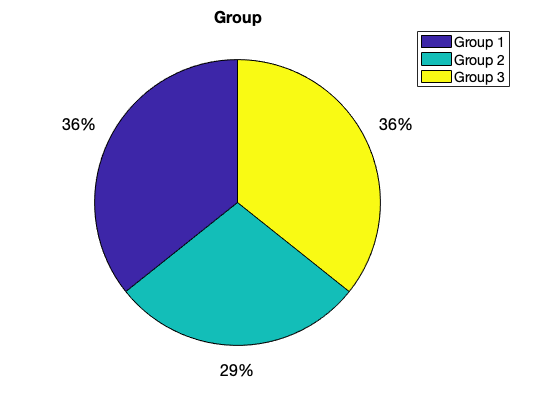

for i = 1:num_participants
    data{i,"Var3"}{1} = erase(data{i,"Var3"}{1}, "number ");
end

figure, createPieChart("Var3", data, "Group", false);

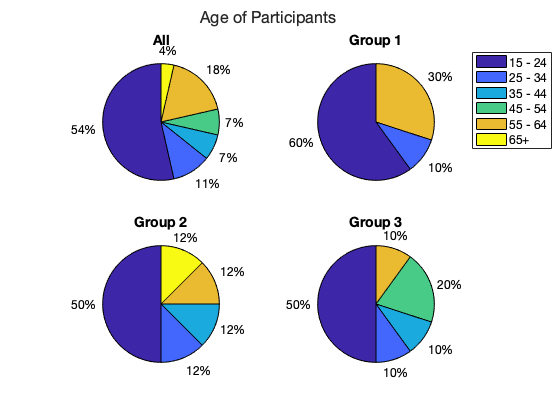

figure, createPieChart("Var4", data, "Age of Participants", true);

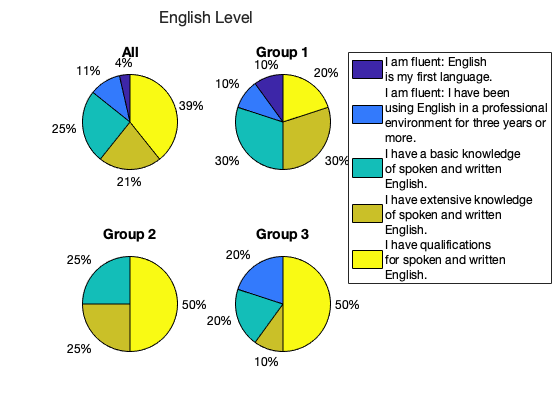

figure, createPieChart("Var5", data, "English Level", true);

## Analysis of Answers

### Hypothesis 1: Do users prefer to learn a language using voice interfaces over keyboard interfaces?

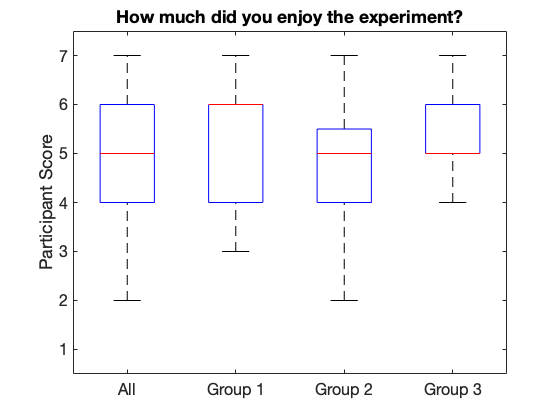

figure, createBoxPlots(7, data, questions)

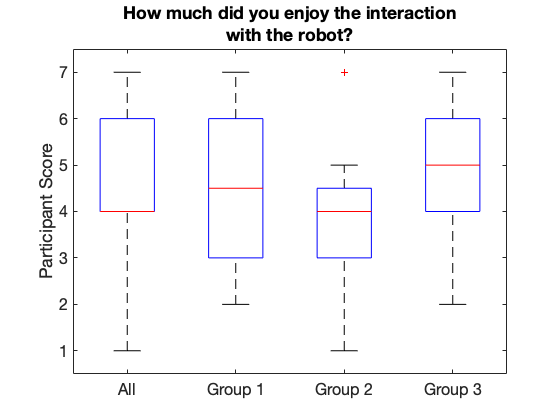

figure, createBoxPlots(8, data, questions)

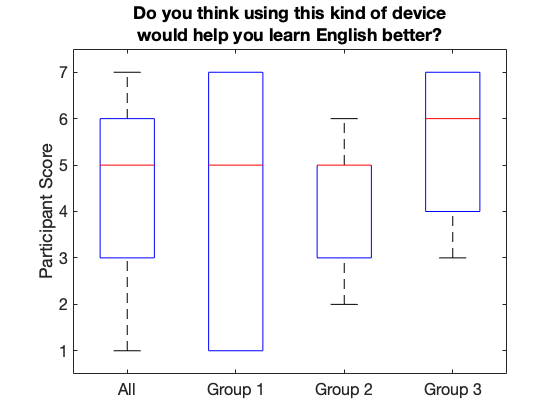

figure, createBoxPlots(9, data, questions)

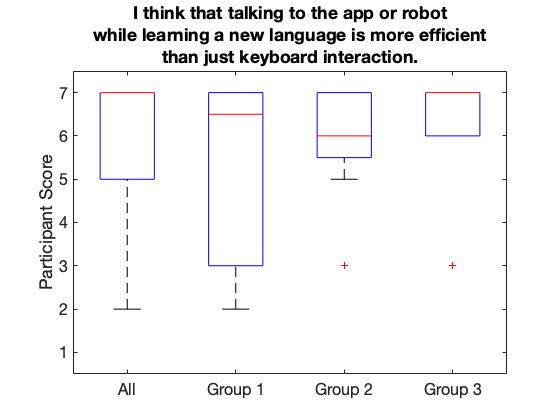

figure, createBoxPlots(17, data, questions)

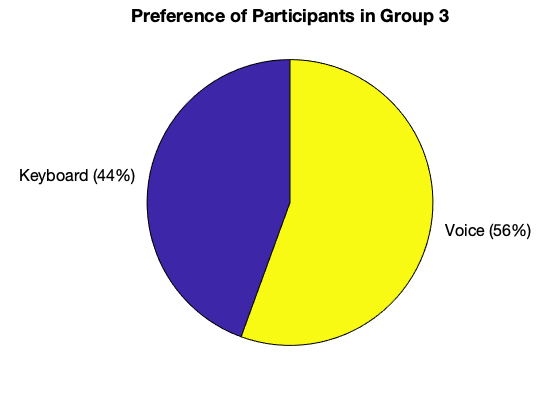

q18 = categorical(data{data{:,"Var3"}=="Group 3","Var18"});
figure, h = pie(q18);
title("Preference of Participants in Group 3", 'FontSize', 18)
set(h(2:2:end),'FontSize', 16);

### Hypothesis 2: The older the user is, the more important vocal interaction is when using technology.

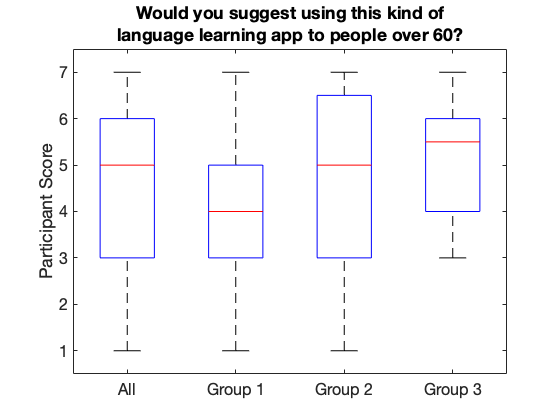

figure, createBoxPlots(11, data, questions)

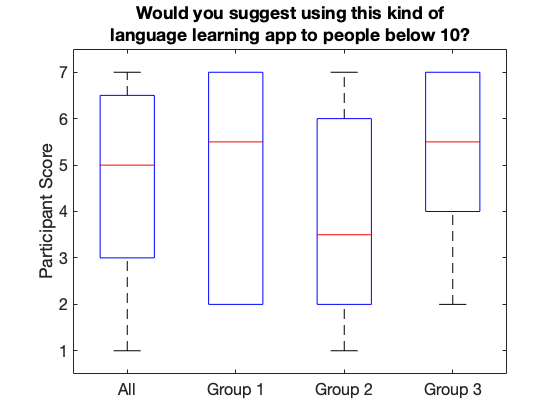

figure, createBoxPlots(12, data, questions)

age = categorical(data.Var4);
q17 = categorical(data.Var17);
q17 = setcats(q17,{'1','2','3','4','5','6','7'});

q17 = 28×1 categorical array
     7 
     6 
     7 
     7 
     6 
     7 
     7 
     7 
     6 
     6 
     7 
     7 
     7 
     3 
     3 
     3 
     7 
     5 
     7 
     6 
     2 
     2 
     7 
     7 
     7 
     3 
     7 
     5 


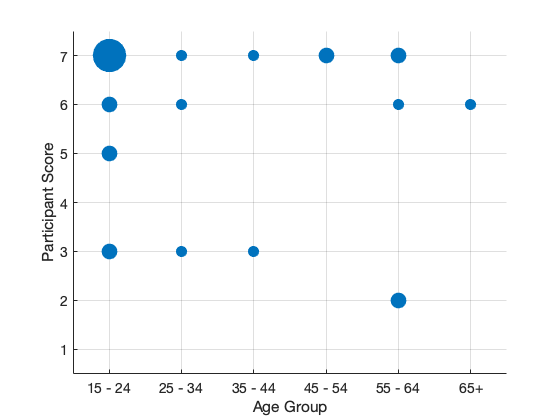


[uxy, jnk, idx] = unique([age, q17],'rows');
szscale = histc(idx,unique(idx));

figure, grid on, hold on
h = scatter(age(jnk), q17(jnk),'filled','sizedata',szscale*125);

ax = gca;
ylabel("Participant Score"), xlabel("Age Group")
ax.YAxis.FontSize = 16; ax.XAxis.FontSize = 16;
labels = categories(age);
for i = 1:length(labels)
    labels{i} = erase(labels{i}, " years old");
end

set(gca,'yticklabel', categories(q17),'FontSize', 14)
set(gca,'xticklabel',labels,'FontSize', 14)

### Hypothesis 3: If the robot shows emotion, the experience becomes more enjoyable.

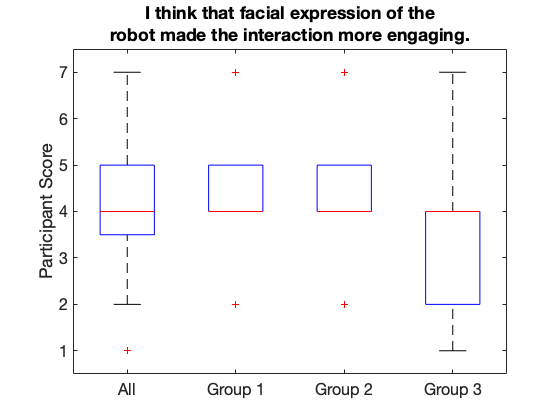

figure, createBoxPlots(16, data, questions)

### Other

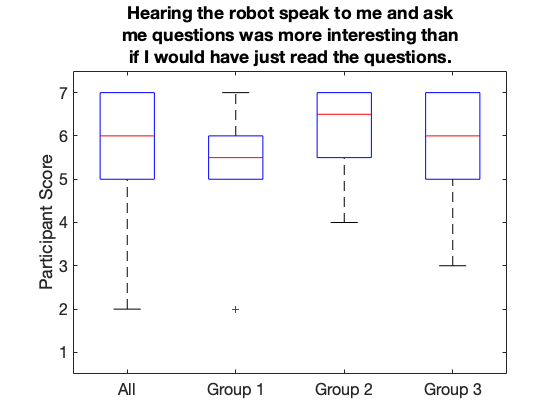

figure, createBoxPlots(15, data, questions)